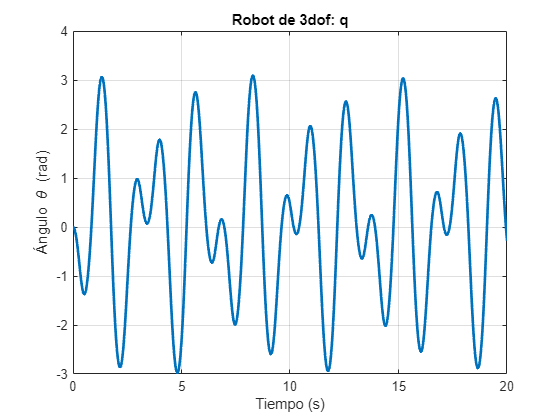

function dxdt = RobotDynamics3dof(~, x, g, params, tau)

    m11 = cos(x(2))^2*params(1) + cos(x(2))*cos(x(2) + x(3))*params(2) + sin(x(2) + x(3))*params(3);
    m22 = params(1) + 2*cos(x(3))*params(2) + params(3);
    m23 = cos(x(3)) * params(2) + params(3);
    m32 = cos(x(3)) * params(2) + params(3);
    m33 = params(3);

    M = [m11 0   0;
        0   m22 m23;
        0   m32 m33];

    c11 = -cos(x(2))*sin(x(2))*x(5)*params(1) - 1/2*(cos(x(2))*sin(x(2) + x(3))*(x(5) + x(6)) + sin(x(2))*cos(x(2) + x(3))*x(5))*params(2) + cos(x(2) + x(3))*sin(x(2) + x(3))*(x(5) + x(6))*params(3);
    c12 = -cos(x(2))*sin(x(2))*x(4)*params(1) - 1/2*(sin(x(2))*cos(x(2) + x(3)) + cos(x(2))*sin(x(2) + x(3)))*x(4)*params(2) + sin(x(2) + x(3))*cos(x(2) + x(3))*x(4)*params(3);
    c13 = -1/2*cos(x(2))*sin(x(2) + x(3))*x(4)*params(2) + cos(x(2) + x(3))*sin(x(2) + x(3))*x(4)*params(3);
    c21 = cos(x(2))*sin(x(2))*x(4)*params(1) + 1/2*(sin(x(2))*cos(x(2) + x(3)) + cos(x(2))*sin(x(2) + x(3)))*x(4)*params(2) - sin(x(2) + x(3))*cos(x(2) + x(3))*x(4)*params(3);
    c22 = -sin(x(3))*x(6)*params(2);
    c23 = -sin(x(3))*(x(5) + x(6))*params(2);
    c31 = 1/2*cos(x(2))*sin(x(2) + x(3))*x(4)*params(2) - cos(x(2) + x(3))*sin(x(2) + x(3))*x(4)*params(3);
    c32 = sin(x(5))*params(2);
    c33 = 0;

    C = [c11 c12 c13;
         c21 c22 c23;
         c31 c32 c33];

    g2 = g*(cos(x(2))*params(7) + cos(x(2) + x(3))*params(8));
    g3 = g*cos(x(2) + x(3))*params(8);

    g = [0;
        g2;
        g3];
    
    q_dot = [x(4); x(5); x(6)];

    q_ddot = inv(M) * (tau - C * q_dot - g);

    dxdt = [q_dot;
        q_ddot];
end

format long

params = [  4.53641
            0.341864
            4.503919
            1.373760
            1.188021
            0.553657
            4.948273
            12.955526
          ] * 1e-3;

x0 = [0; 0; 0; 0; 0; 0];
tspan = 0:0.01:20;
tau = 0;
g = 9.81;

[t, x] = ode45(@(t,x) RobotDynamics3dof(t, x, g, params, tau), tspan, x0);

figure;
plot(t, x(:,3), 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Ángulo \theta (rad)');
title('Robot de 3dof: q');
grid on;